# YOLOv2 Object Detection

# Part 1: Data Preparation

Copyright 2018-2020 The MathWorks, Inc.

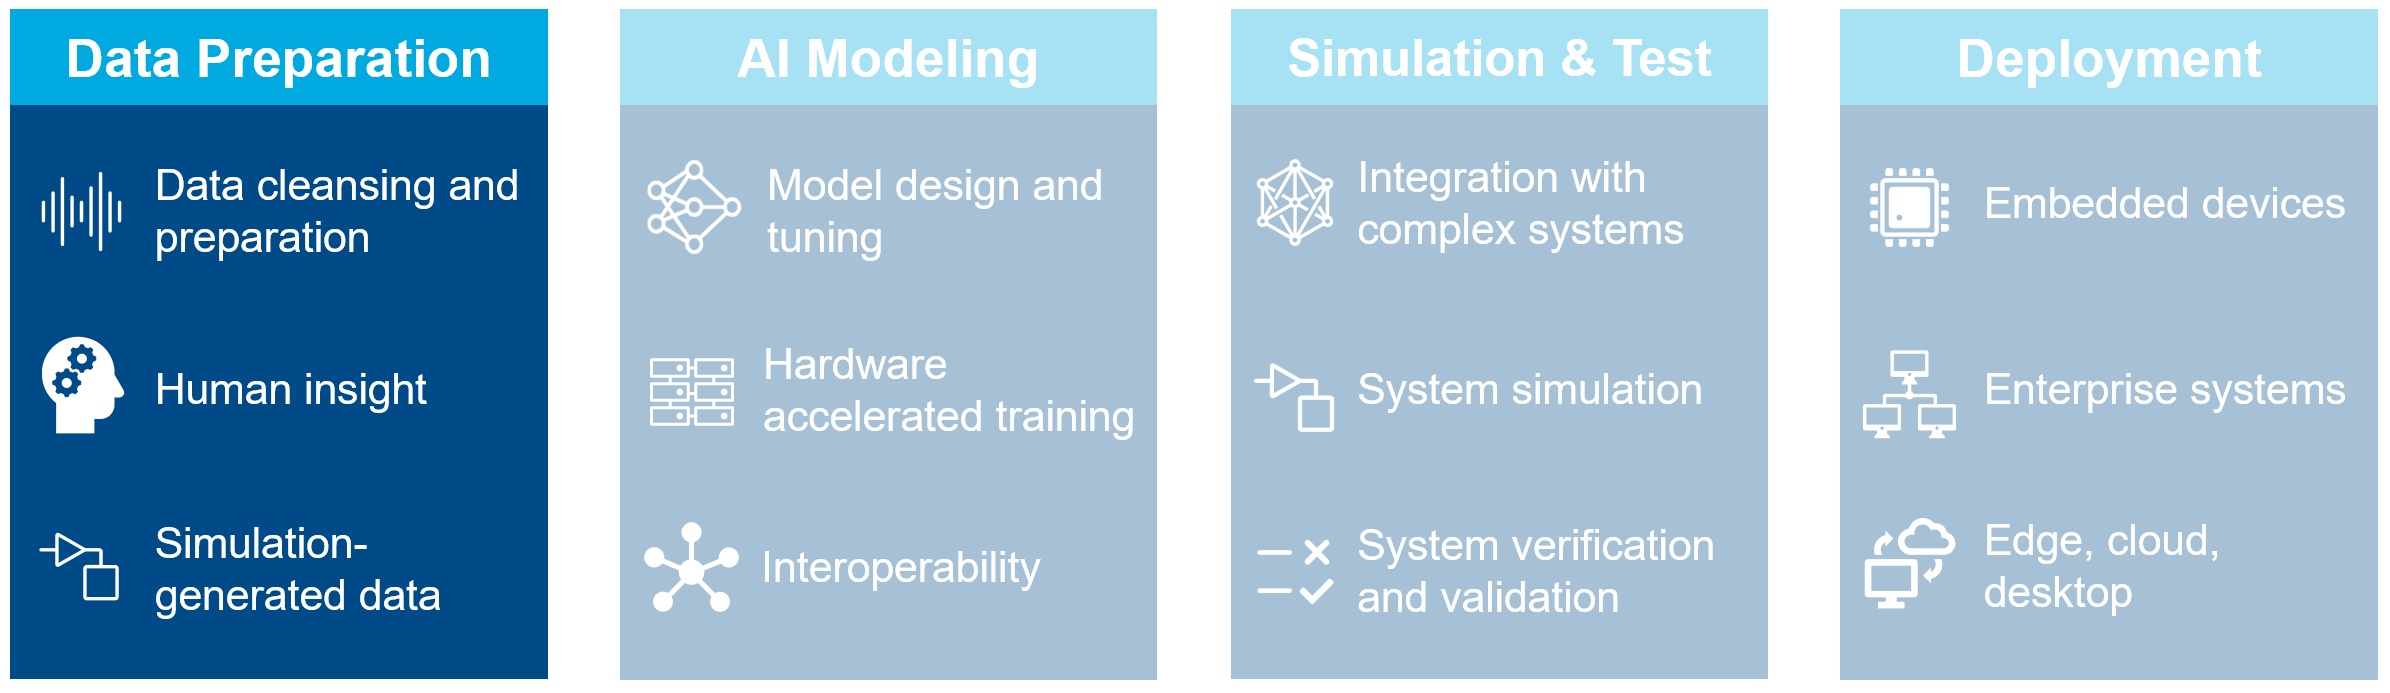

## Configuration

Make sure we run this as a project.

try
    prj = currentProject;
catch
    open("YOLOv2ObjectDetection.prj");
    OpenPart1;
    prj = currentProject;
end

## Labeling Data

For any supervised deep learning project to be successful, you will need to label data. We will use the image labeling apps to label data.

imds = imageDatastore(fullfile("vehicleImages/"));
imageLabeler(imds)

### Define Label and Automate Labeling

After opening the labeler app in the section above, create a label called "vehicle" and try labeling some images. After manually labeling some images, try using the ACF Vehicle Detector in the Algorithm section to automate the processing of the images.

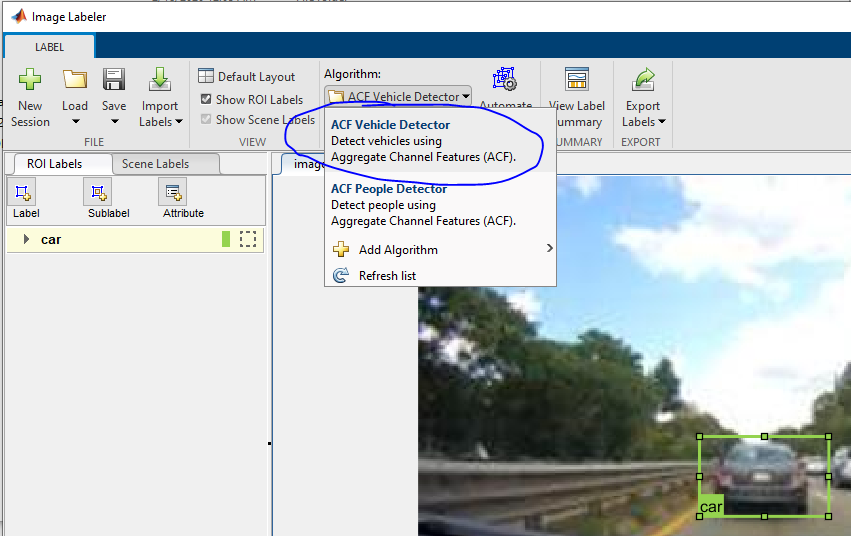

### Export Labels as a Ground Truth Object

Once a sufficient number of images are labeled, export the ground truth data so that it can be used later to train a model.